# Distributed Drone Collision Avoidance

ADMM based collision avoidance, using a double integrator model.

First define the reference and initial positions/ states as well as the model matrices. Model equation is x(k+1) = Ax(k)+Bu(k), with x being the state vector comprised of a 3D position and 3D velocity, input u is 3D acceleration.

clear;
T = 0.1; %time step

r = [1.0,1.4,0,0,0,0;
     0.6,0.4,0,0,0,0;
     0,0.9,0,0,0,0];

x0 = [0,0.5,0,0,0,0; 
       0.2,0.9,0,0,0,0;
       1.0,0.3,0,0,0,0];

A = [1 0 0 T 0 0;
    0 1 0 0 T 0;
    0 0 1 0 0 T;
    0 0 0 1 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1];

B = [0 0 0;
    0 0 0;
    0 0 0;
    T 0 0;
    0 T 0;
    0 0 T];

M = size(x0,1); % Number of agents

nx = 6; %state vector dimension
nu = 3; %number of inputs
Nd = 3; %number of dimensions

Define matrices for LQR, define Q to only weight position.


N = 100; %Time horizon
Q = eye(Nd)*10; 
Q = blkdiag(Q,zeros(nx-Nd));
R = eye(nu)*13;

Define vectors for ADMM iterations

N_j = zeros(M,M-1); %Matrix for indices of all other agents
for i = 1:M
    temp = 1:M;
    temp(i) = [];
    N_j(i,:) = temp;
end

rho = 40; %weighting of constraint violation

lambda = zeros(Nd,1); %Lagrangian variable
lambda_to_ = zeros(Nd,1); %used to construct lagrangians for each agent
lambda_from_ = zeros(Nd,1);

w = zeros(Nd,1); %Will effectively be the proposed trajectory by one drone for another
x = zeros(nx,1);
w_from_ = zeros(Nd,1);
w_to_ = zeros(Nd,1);

lambda = repmat(lambda, N+1, M);

lambda_to_j = cell(M,1);
lambda_from_j = cell(M,1);
w_to_j = cell(M,1);
w_from_j = cell(M,1);

for i = 1:M
    lambda_to_j{i} = repmat(lambda_to_, N+1, M-1);
    lambda_from_j{i} = repmat(lambda_from_, N+1, M-1);
    w_from_j{i} = repmat(w_from_, N+1, M-1);
    w_to_j{i} = repmat(w_to_, N+1, M-1);
end
w = repmat(w, N+1, M);
x = repmat(x, N+1, M);


delta = 0.5; % Inter-agent distance

We now define some other useful matrices

posM = blkdiag(eye(Nd),zeros(nx-Nd)); % Matrix to take only position from the state vector x (zeros rest)
d = [eye(Nd),zeros(Nd,nx-Nd)]; % Matrix to take only position from the state vector x (only returns pos)
posMN = kron(eye(N+1),d); %returns pos across time steps

rhoM = kron(speye((N+1)),rho/2*eye(nu)); % matrix for the quadratic objective formualation

% Transformation matrix H creation
% Multiplies state vector to return a vector consisting of difference in
% positions between agents

H = kron(eye(N+1),repmat(d, M-1, 1));
Hw = kron(eye(N+1),repmat(eye(nu), M-1, 1));
for i = 1:(M-1)
    v = zeros(M-1,1);
    v(i) = 1;
    H_M = kron(eye(N+1),kron(v, -1*d));
    H_Mw = kron(eye(N+1),kron(v, -1*eye(nu)));
    
    H =  [H, H_M];
    Hw = [Hw,H_Mw];
end

We now move on to set up the MPC constraints (i.e. ensuring agents follow the model for all timesteps)

%% The MPC Problem
% Cast MPC problem to a QP: x = (x(0),x(1),...,x(N),u(0),...,u(N-1))

% - quadratic objective for prediction
P = blkdiag( kron(speye(N), Q ), Q, kron(speye(N), R) );
P_new = blkdiag( kron(speye(N), Q+ M*rho/2*posM ), Q+M*rho/2*posM, kron(speye(N), R) );
% - linear dynamics
Ax = kron(speye(N+1), -speye(nx)) + kron(sparse(diag(ones(N, 1), -1)), A);
Bu = kron([sparse(1, N); speye(N)], B);
Aeq = [Ax, Bu];
% quadratic objective for coordination

Pc = kron(eye(M),rhoM);

u_bound = zeros((N+1)*nx+N*nu,M);
l_bound = zeros((N+1)*nx+N*nu,M);
b_eq = zeros((N+1)*nx,M);

for i = 1:M
    
    % input constraints (here just between 1 & -1)
    umin = ones(nu,1)*-1;
    umax = ones(nu,1)*1;
    
    min_input = repmat(umin,N,1);
    max_input = repmat(umax,N,1);
    % - linear dynamics
    
    u_bound(:,i) = [inf((N+1)*nx,1);max_input];
    l_bound(:,i) = [-inf((N+1)*nx,1);min_input];
    
    b_eq(:,i) = [-x0(i,:)'; zeros(N*nx, 1)];
        
end

## Optimisation step

Performs the optimisation, iteratively optimises the state vector (prediction step), then updates w (to consider collision avoidance) then mediates & communicates, updating lagrangian vectors.

res = zeros((N+1)*nx+N*nu,M);
q = zeros((N+1)*nx+N*nu,M);
qc = zeros(M*(N+1)*Nd);
A_ineq = cell(M,1);
l_ineq = zeros((M-1)*N,M);
resc = zeros(M*(N+1)*Nd,M);
addpath Funz;
qp_opts = optimoptions('quadprog','Display','off');
for nit = 1:45
    
    %% Prediction
    for i = 1:M
        
        q(:,i) = prediction_linear(lambda(:,i),lambda_from_j{i},w(:,i),w_from_j{i},rho,r(i,:)',Q,Q,N,nu,M,posMN);

        res(:,i) = quadprog(P_new,q(:,i),[],[], Aeq,b_eq(:,i),l_bound(:,i),u_bound(:,i),[],qp_opts);
        x(:,i) = res(1:nx*(N+1),i);
    end
    
    %% Communication (update) and Coordination
    for i = 1:M    
        %- linear objective for coordination
        qc(:,i) = coordination_linear(i,lambda(:,i),lambda_to_j{i},rho,N_j(i,:),M,x,posMN);
        
        % Update matrices
        [A_ineq{i},l_ineq(:,i)] = communicate(i,x,N,N_j(i,:),M,H,Hw,delta,nu);
        resc(:,i) = quadprog(Pc,qc(:,i),-A_ineq{i},-l_ineq(:,i),[],[],[],[],[],qp_opts);
        w(:,i) = resc(1:Nd*(N+1),i);
        
        for j = 1:(M-1)
            w_to_j{i}(:,j) = resc(j*Nd*(N+1)+1:(j+1)*Nd*(N+1),i);
        end
        
    end
    %% Mediation
    
    for i = 1:M
        lambda(:,i) = lambda(:,i) + rho * (posMN * x(:,i)-w(:,i));
        for j = 1:(M-1)
            lambda_to_j{i}(:,j) = lambda_to_j{i}(:,j) + rho * (posMN*x(:,N_j(i,j)) - w_to_j{i}(:,j));
        end
    end
    %% Final Communication
    
    for i = 1:M
        for j = 1:(M-1)
            lambda_from_j{i}(:,j) = lambda_to_j{N_j(i,j)}(:,(N_j(N_j(i,j),:)==i));
            w_from_j{i}(:,j) = w_to_j{N_j(i,j)}(:,(N_j(N_j(i,j),:)==i));
        end
        
    end
    
end

## Visualise trajectories

Visualises predicted trajectories

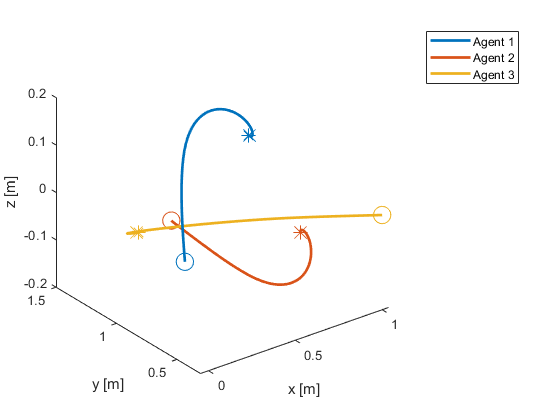

visualise_drones_3d(r,x,N,T)